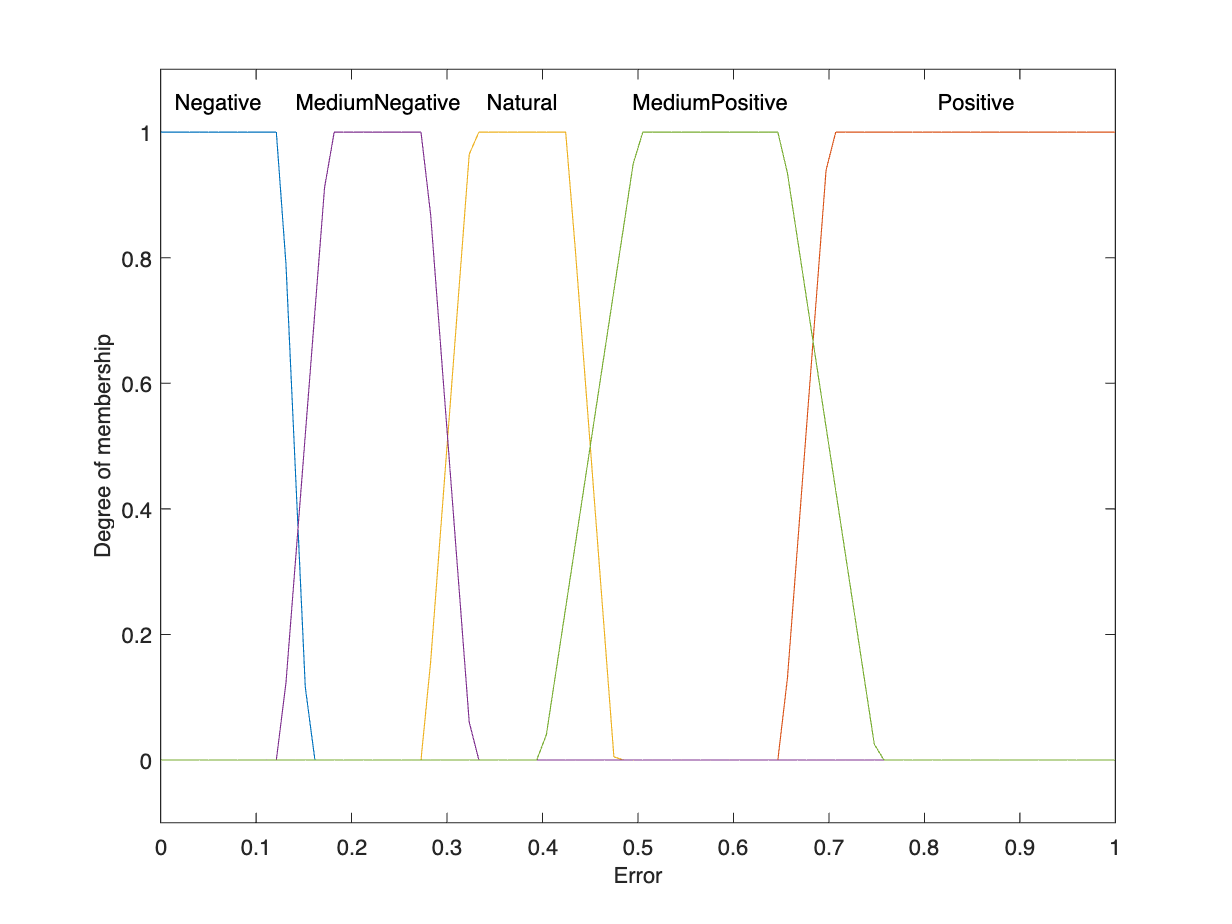

%Neurofeedback Fuzzy MISO
%% Version V1
% Authors - Mario De Los Santos, Felipe Orihuela-Espina,
% Javier Herrara-Vega, Gustavo Rodriguez, Javier Andreu-Perez
% Date - August 3rd, 2022
% Email - madlsh3517@gmail.com

cFNIRS_MISO_v3 = mamfis(...
    'NumInputs', 1, 'NumInputMFs', 2, ...
    'NumOutputs', 1, 'NumOutputMFs', 5, ...
    'AddRule', 'none');


%SHAPES
% S-shape: smf : [i e];
% Z-shaped: zmf: [i e];
% Bell-shape: gbellmf: [i, o, e];

cFNIRS_MISO_v3.Inputs(1).Name = 'Error';
cFNIRS_MISO_v3.Inputs(1).Range = [0, 1]; 
%Membership function shapes
cFNIRS_MISO_v3.Inputs(1).MembershipFunctions(1).Name = 'Negative';
cFNIRS_MISO_v3.Inputs(1).MembershipFunctions(1).Type ='trapmf'; 
cFNIRS_MISO_v3.Inputs(1).MembershipFunctions(1).Parameters = [-0.05 0 0.125 0.155];

cFNIRS_MISO_v3.Inputs(1).MembershipFunctions(4).Name = 'MediumNegative';
cFNIRS_MISO_v3.Inputs(1).MembershipFunctions(4).Type ='trapmf'; 
cFNIRS_MISO_v3.Inputs(1).MembershipFunctions(4).Parameters =[0.125 0.17625 0.27625 0.32625];

cFNIRS_MISO_v3.Inputs(1).MembershipFunctions(3).Name = 'Natural';
cFNIRS_MISO_v3.Inputs(1).MembershipFunctions(3).Type ='trapmf'; 
cFNIRS_MISO_v3.Inputs(1).MembershipFunctions(3).Parameters = [0.275 0.325 0.425 0.475];

cFNIRS_MISO_v3.Inputs(1).MembershipFunctions(5).Name = 'MediumPositive';
cFNIRS_MISO_v3.Inputs(1).MembershipFunctions(5).Type ='trapmf'; 
cFNIRS_MISO_v3.Inputs(1).MembershipFunctions(5).Parameters = [0.4 0.5 0.65 0.75];

cFNIRS_MISO_v3.Inputs(1).MembershipFunctions(2).Name = 'Positive';
cFNIRS_MISO_v3.Inputs(1).MembershipFunctions(2).Type ='trapmf';
cFNIRS_MISO_v3.Inputs(1).MembershipFunctions(2).Parameters = [0.65	0.7 1 1];

plotmf(cFNIRS_MISO_v3, 'input', 1, 100);

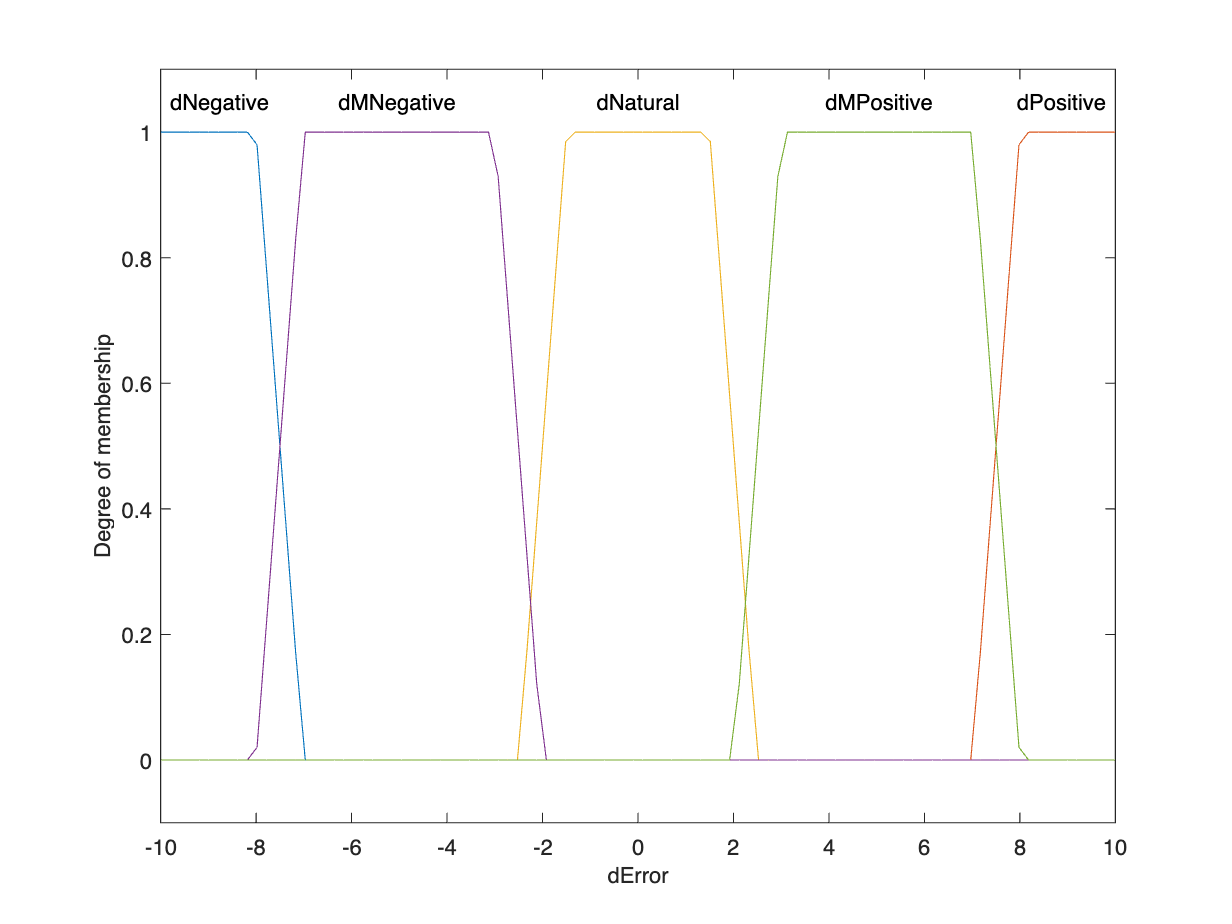


cFNIRS_MISO_v3.Inputs(2).Name = 'dError';
cFNIRS_MISO_v3.Inputs(2).Range = [-10, 10]; 

%Membership function shapes
cFNIRS_MISO_v3.Inputs(2).MembershipFunctions(1).Name = 'dNegative';
cFNIRS_MISO_v3.Inputs(2).MembershipFunctions(1).Type ='trapmf'; 
cFNIRS_MISO_v3.Inputs(2).MembershipFunctions(1).Parameters = [-10 -10 -8 -7];

cFNIRS_MISO_v3.Inputs(2).MembershipFunctions(4).Name = 'dMNegative';
cFNIRS_MISO_v3.Inputs(2).MembershipFunctions(4).Type ='trapmf';
cFNIRS_MISO_v3.Inputs(2).MembershipFunctions(4).Parameters = [-8 -7 -3 -2];

cFNIRS_MISO_v3.Inputs(2).MembershipFunctions(3).Name = 'dNatural';
cFNIRS_MISO_v3.Inputs(2).MembershipFunctions(3).Type ='trapmf';
cFNIRS_MISO_v3.Inputs(2).MembershipFunctions(3).Parameters = [-2.5 -1.5 1.5 2.5];

cFNIRS_MISO_v3.Inputs(2).MembershipFunctions(5).Name = 'dMPositive';
cFNIRS_MISO_v3.Inputs(2).MembershipFunctions(5).Type ='trapmf';
cFNIRS_MISO_v3.Inputs(2).MembershipFunctions(5).Parameters = [2 3 7 8];

cFNIRS_MISO_v3.Inputs(2).MembershipFunctions(2).Name = 'dPositive';
cFNIRS_MISO_v3.Inputs(2).MembershipFunctions(2).Type ='trapmf';
cFNIRS_MISO_v3.Inputs(2).MembershipFunctions(2).Parameters = [7 8 10 10];

plotmf(cFNIRS_MISO_v3, 'input', 2, 100);

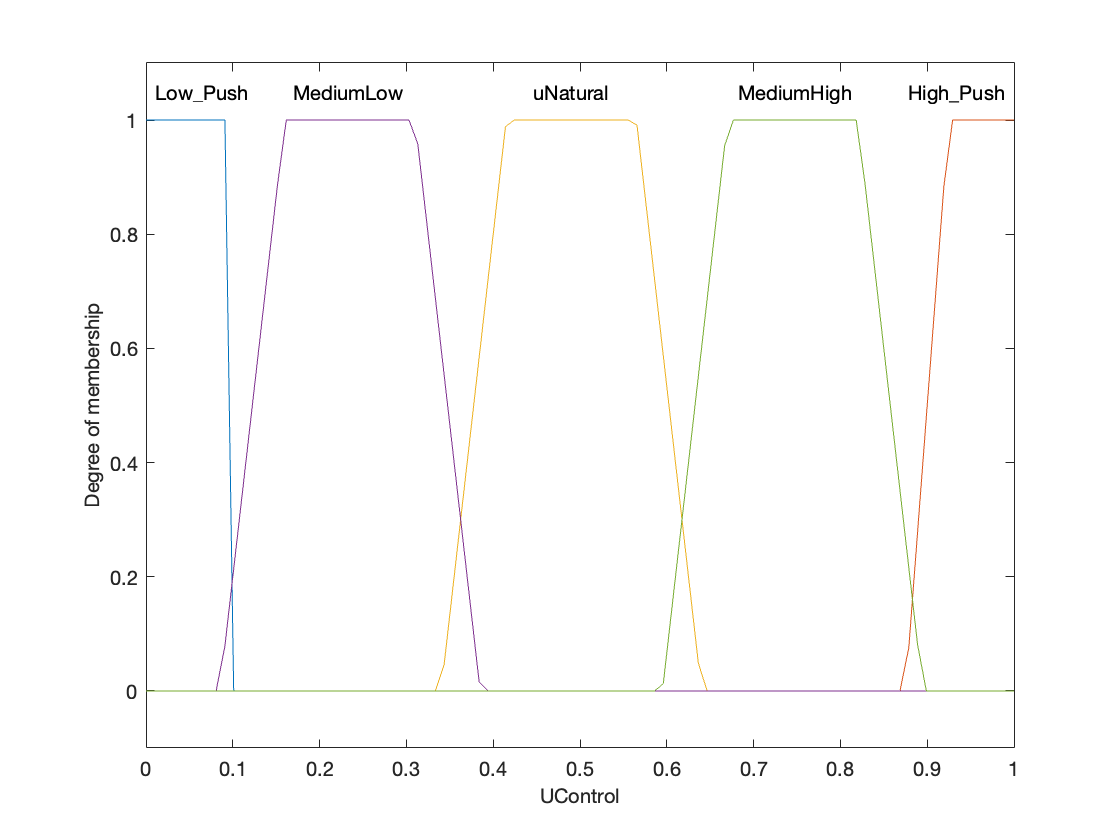

%OUTPUTS
cFNIRS_MISO_v3.Outputs(1).Name = 'UControl';
cFNIRS_MISO_v3.Outputs(1).Range = [0,1];

cFNIRS_MISO_v3.Outputs(1).MembershipFunctions(1).Name = 'Low_Push';
cFNIRS_MISO_v3.Outputs(1).MembershipFunctions(1).Type = 'trapmf'; 
cFNIRS_MISO_v3.Outputs(1).MembershipFunctions(1).Parameters = [0 0 0.095 0.095];

cFNIRS_MISO_v3.Outputs(1).MembershipFunctions(4).Name = 'MediumLow';
cFNIRS_MISO_v3.Outputs(1).MembershipFunctions(4).Type = 'trapmf'; 
cFNIRS_MISO_v3.Outputs(1).MembershipFunctions(4).Parameters = [0.085 0.160 0.310 0.385];

cFNIRS_MISO_v3.Outputs(1).MembershipFunctions(3).Name = 'uNatural';
cFNIRS_MISO_v3.Outputs(1).MembershipFunctions(3).Type = 'trapmf'; 
cFNIRS_MISO_v3.Outputs(1).MembershipFunctions(3).Parameters = [0.34 0.415 0.565 0.640];

cFNIRS_MISO_v3.Outputs(1).MembershipFunctions(5).Name = 'MediumHigh';
cFNIRS_MISO_v3.Outputs(1).MembershipFunctions(5).Type = 'trapmf'; 
cFNIRS_MISO_v3.Outputs(1).MembershipFunctions(5).Parameters = [0.595 0.670 0.820	0.895];

cFNIRS_MISO_v3.Outputs(1).MembershipFunctions(2).Name = 'High_Push';
cFNIRS_MISO_v3.Outputs(1).MembershipFunctions(2).Type = 'trapmf'; 
cFNIRS_MISO_v3.Outputs(1).MembershipFunctions(2).Parameters = [0.875 0.925 1 1];


plotmf(cFNIRS_MISO_v3, 'output', 1, 100);

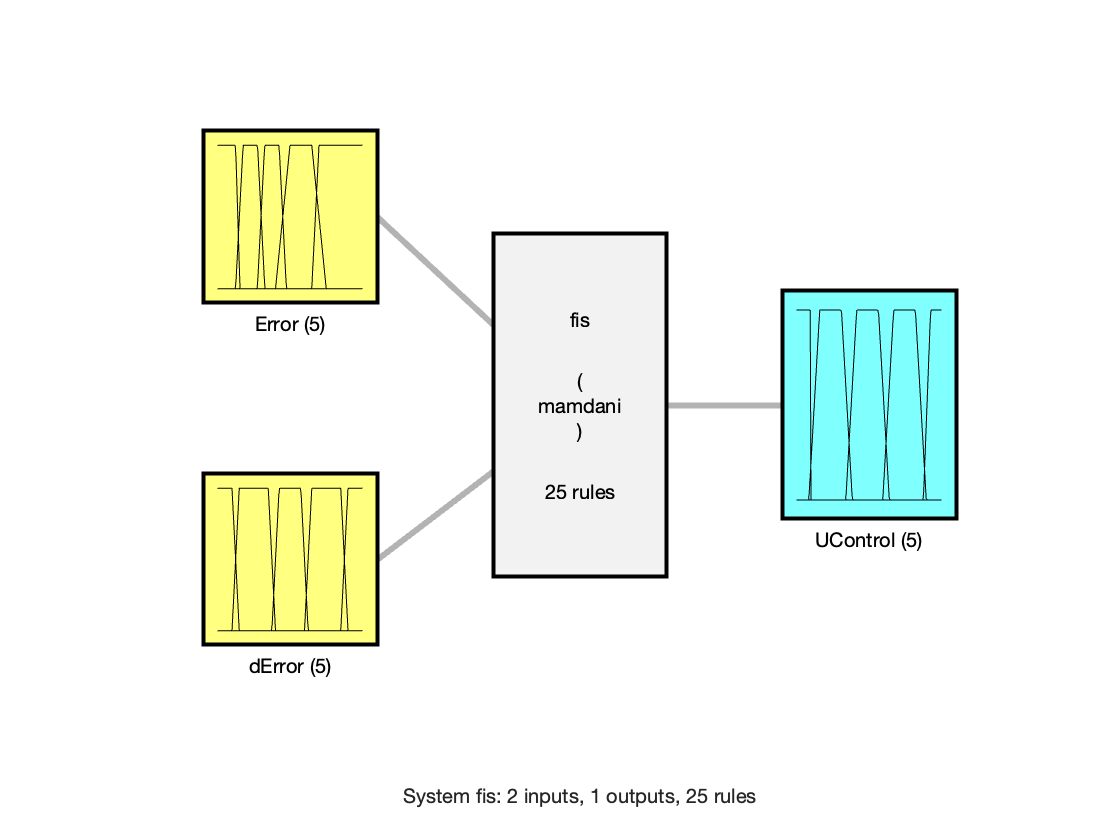

%Rules
rules = [ "If Error is Negative and dError is dNegative then UControl is Low_Push";...
    "If Error is Negative and dError is dMNegative then UControl is Low_Push";...
    "If Error is Negative and dError is dNatural then UControl is Low_Push";...
    "If Error is MediumNegative and dError is dNegative then UControl is Low_Push";...
    "If Error is MediumNegative and dError is dMNegative then UControl is Low_Push";...
    
    %Medium Low
    "If Error is Negative and dError is dMPositive then UControl is MediumLow";...
    "If Error is Negative and dError is dPositive then UControl is MediumLow";...
    "If Error is MediumNegative and dError is dNatural then UControl is MediumLow";...
    "If Error is MediumNegative and dError is dMPositive then UControl is MediumLow";...
    "If Error is MediumNegative and dError is dPositive then UControl is MediumLow";...
    
    %Natural
    "If Error is Natural and dError is dNegative then UControl is uNatural";...
    "If Error is Natural and dError is dMNegative then UControl is uNatural";...
    "If Error is Natural and dError is dNatural then UControl is uNatural";...
    "If Error is Natural and dError is dMPositive then UControl is uNatural";...
    "If Error is Natural and dError is dPositive then UControl is uNatural";...
    
    %Medium High
    "If Error is MediumPositive and dError is dNegative then UControl is MediumHigh";...
    "If Error is MediumPositive and dError is dMNegative then UControl is MediumHigh";...
    "If Error is MediumPositive and dError is dNatural then UControl is MediumHigh";...
    "If Error is Positive and dError is dNegative then UControl is MediumHigh";...
    "If Error is Positive and dError is dMNegative then UControl is MediumHigh";...

    %High Push
    "If Error is MediumPositive and dError is dMPositive then UControl is MediumHigh";...
    "If Error is MediumPositive and dError is dPositive then UControl is MediumHigh";...
    "If Error is Positive and dError is dNatural then UControl is High_Push";...
    "If Error is Positive and dError is dMPositive then UControl is High_Push";...
    "If Error is Positive and dError is dPositive then UControl is High_Push"];

cFNIRS_MISO_v3 = addRule(cFNIRS_MISO_v3,rules);

figure
plotfis(cFNIRS_MISO_v3)

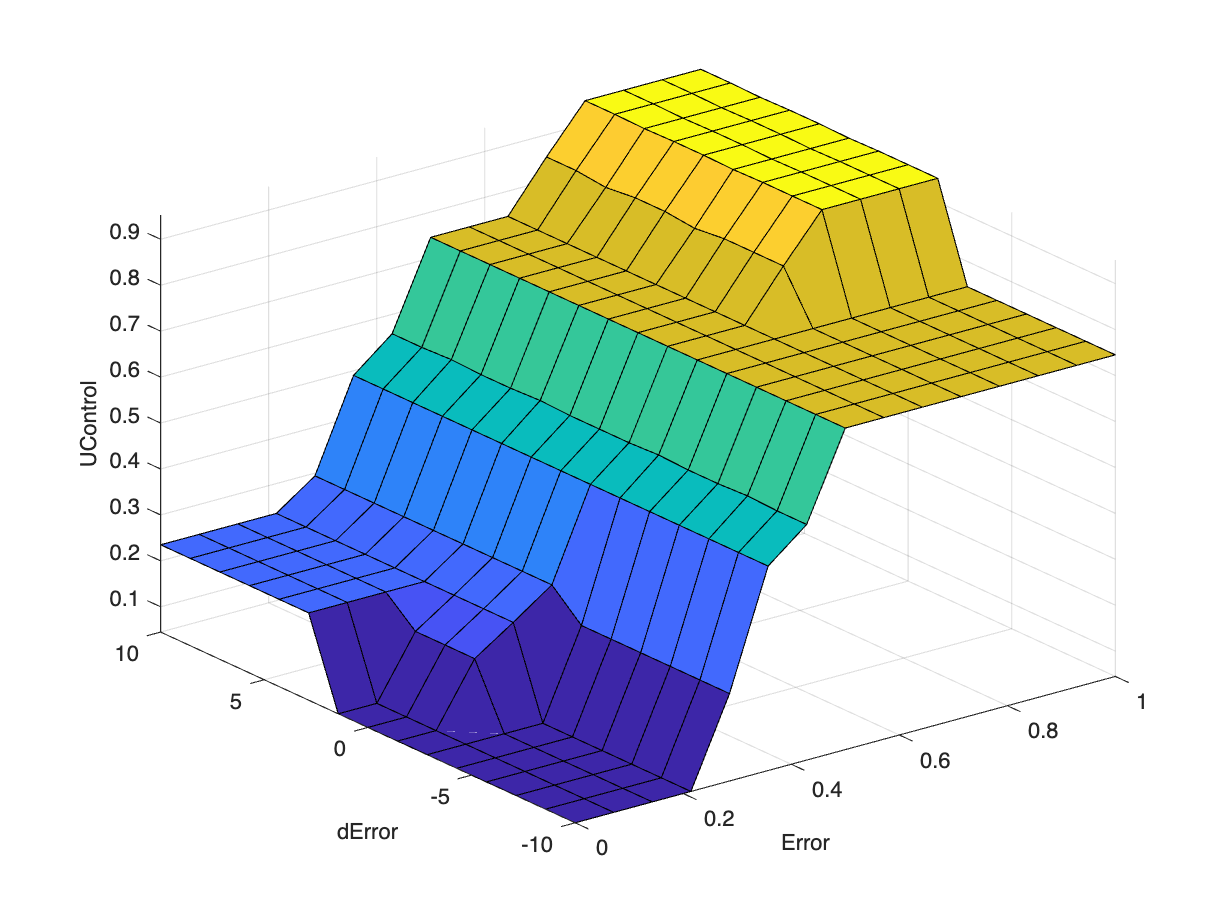

gensurf(cFNIRS_MISO_v3)

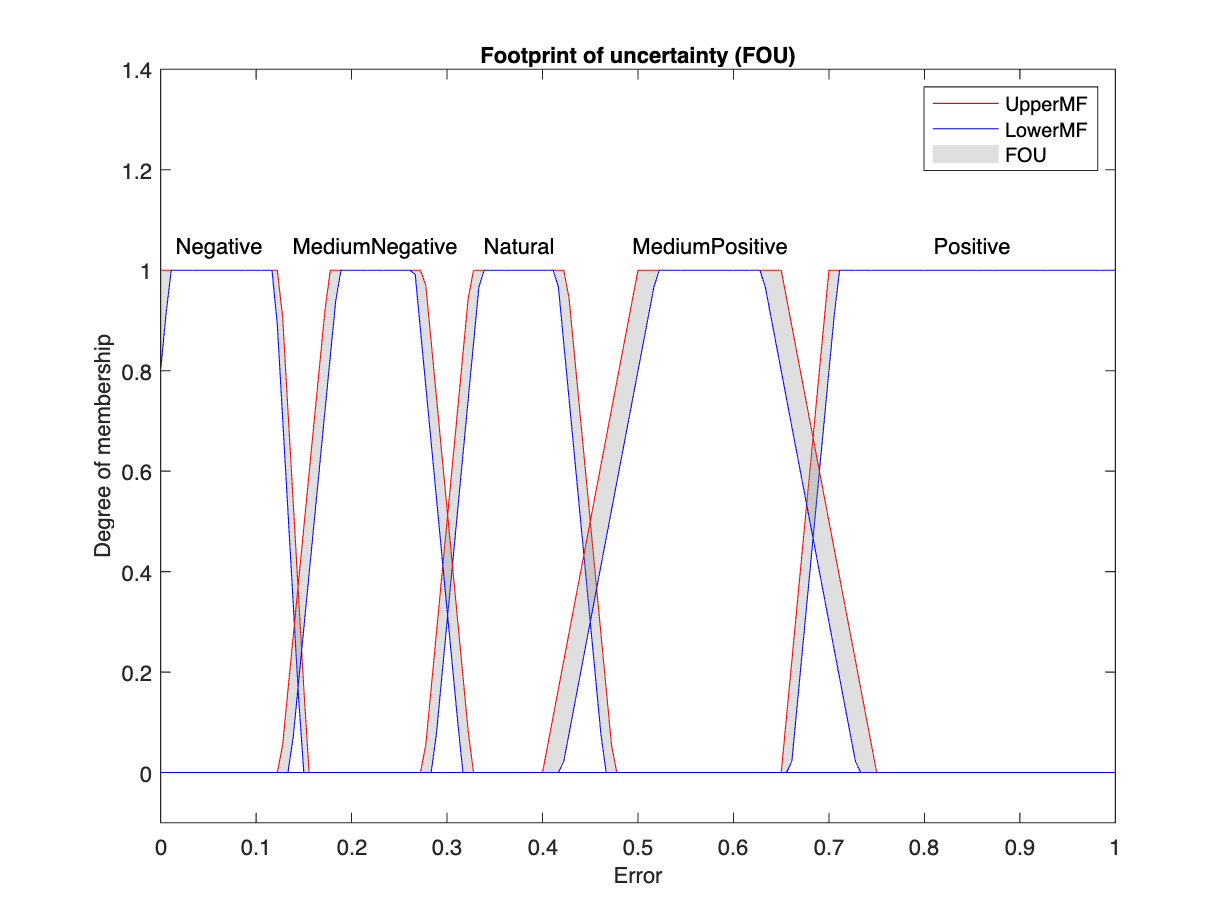

cFNIRS_MISO_v3_type2 =  convertToType2(cFNIRS_MISO_v3);
plotmf(cFNIRS_MISO_v3_type2, "input", 1);